function [x,v,H] = Simulation(x_0, v_0, m, sigma, k_inter, k_center, t_max, dt)
%{
TAKES initial condition vectors x_0, v_0; sim params t_max, dt:

    Vector x_0:
    (
    (x1,x2,x3)1,
    (x1,x2,x3)2,
    ...
    (x1,x2,x3)N
    ),

    Vector v_0:
    (
    (v1,v2,v3)1,
    (v1,v2,v3)2,
    ...
    (v1,v2,v3)N
    )

    Vector m (Nx1): 
    ()
    Scalar time cutoff t_max, step size dt.

RETURNS tensor of:
  positions vs. time
  velocities vs. time
  and E vs. time

    tensor x: (t,N,3)
    (
    (x1,x2,x3)1t1, (x1,x2,x3)1t2,...(x1,x2,x3)1t_max,
    (x1,x2,x3)2t1, (x1,x2,x3)2t2,...(x1,x2,x3)2t_max,
    ...
    (x1,x2,x3)Nt1, (x1,x2,x3)Nt2,...(x1,x2,x3)Nt1_max,
    ),
    tensor v: (t,N,3)
    Same thing
    list E (t)
%}
    if size(x_0, 1) == 1
        x_0 = squeeze(x_0);
        v_0 = squeeze(v_0);
    end
    N = size(x_0, 1);
    num_t_steps = cast(t_max / dt, 'uint64'); % round to correct timesteps
    
    % t_max_round = dt * num_t_steps; % round to correct timesteps

    x = zeros(num_t_steps + 1, N, 3);
    v = zeros(num_t_steps + 1, N, 3);
    m_reshaped = reshape(m, [1, numel(m), 1]);
    
    % Set initial conditions
    x(1,:,:) = x_0;
    v(1,:,:) = v_0;
    
    H = zeros(num_t_steps + 1, 1);
    H(1) = calculate_energy(squeeze(x(1,:,:)), squeeze(v(1,:,:)), m, sigma, k_inter, k_center);
    
    for step = 1:num_t_steps % next step is at step + 1; loop doesn't go there
        x_now = x(step,:,:);
        v_now = v(step,:,:);
        F_now = calculate_force(x_now, sigma, k_inter, k_center);

        % ADD DAMPING HERE IF YOU LIKE; AN ADDITIONAL W*V TERM

        x_next = x_now + v_now * dt + (F_now./(2*m_reshaped) * dt^2);
        F_next = calculate_force(x_next, sigma, k_inter, k_center);

        v_next = v_now + ((dt* (F_now + F_next)./(2*m_reshaped)));

        x(step + 1,:,:) = x_next;
        v(step + 1,:,:) = v_next;
        H(step + 1) = calculate_energy(squeeze(x_next), squeeze(v_next), m, sigma, k_inter, k_center);
    end

end

function F = calculate_force(x_t, sigma, k_inter, k_center)
% takes a vector of particle states at a given time t.
% takes vectors of diameters
% assume center is 0 0 0
% returns an Nx3 vector of forces
    x_t = squeeze(x_t);

    N = size(x_t,1);
    x_center = zeros(N,3);
    
    % CENTRAL FORCE
    F = k_center * (x_center - x_t);

    % INTERACTION FORCES
    for i = 1:(N-1)
        for j = (i+1):N
            distance = norm(x_t(i,:)-x_t(j,:));

            F(i,:) = F(i,:)...
                + k_inter * Heaviside((sigma(i) + sigma(j))/2 - distance) * (x_t(i,:) - x_t(j,:))...
                * (((sigma(i)+sigma(j))/(2 * distance))-1); % j on i
            F(j,:) = F(j,:)...
                + k_inter * Heaviside((sigma(j) + sigma(i))/2 - distance) * (x_t(j,:) - x_t(i,:))...
                * (((sigma(i)+sigma(j))/(2 * distance))-1); % i on j
        end
    end
    F = reshape(F, [1, size(F)]);
end 

function S = Heaviside(x)
% Implementation of the Heaviside Step Function
    if ~isscalar(x)
        error('input is not a scalar')
    end
    if x < 0
        S = 0;
    else
        S = 1;
    end
end

function H = calculate_energy(x_t, v_t, m, sigma, k_inter, k_center)
% assume center is 0 0 0
% returns scalar energy value
    N = size(x_t, 1);
    x_center = zeros(N,3);
    
    T = (1/2) * sum(sum(m .* (v_t.^2)));

    V_center = sum(0.5*k_center*vecnorm(x_t - x_center, 2 , 2).^2);

    V_inter = 0;
    for i = 1:(N-1)
        for j = (i+1):N
            distance = norm(x_t(i,:) - x_t(j,:));
            overlap = max(0, (sigma(i) + sigma(j))/2 - distance);
            V_inter = V_inter + 0.5 * k_inter * overlap^2;
        end
    end
    H = T + V_center + V_inter;
end

function combined_visualization(x, v, H, sigma, m, dt, step_interval)
    [num_steps, num_particles, ~] = size(x);
    t = (0:num_steps-1) * dt;

    % Calculate average displacement and momentum
    avg_displacement = squeeze(mean(sqrt(sum(x.^2, 3)), 2));
    avg_momentum = squeeze(mean(sqrt(sum((v .* reshape(m, [1, num_particles, 1])).^2, 3)), 2));

    % Calculate best fit lines
    p_displacement = polyfit(t, avg_displacement, 1);
    p_momentum = polyfit(t, avg_momentum, 1);
    fit_displacement = polyval(p_displacement, t);
    fit_momentum = polyval(p_momentum, t);

    % Create figure with two subplots
    fig = figure('Position', [100, 100, 1200, 500]);
    ax1 = subplot(1, 2, 1);
    ax2 = subplot(1, 2, 2);

    % Set up combined plot for energy, displacement, and momentum
    yyaxis(ax1, 'left');
    plot(ax1, t, H, 'b-', 'DisplayName', 'Energy');
    ylabel(ax1, 'Energy');
    hold(ax1, 'on');
    
    yyaxis(ax1, 'right');
    plot(ax1, t, avg_displacement, 'g-', 'DisplayName', 'Avg Displacement');
    plot(ax1, t, fit_displacement, 'g--', 'DisplayName', 'Displacement Fit');
    plot(ax1, t, avg_momentum, 'm-', 'DisplayName', 'Avg Momentum');
    plot(ax1, t, fit_momentum, 'm--', 'DisplayName', 'Momentum Fit');
    ylabel(ax1, 'Avg Displacement / Momentum');
    
    xlabel(ax1, 'Time');
    title(ax1, 'Energy, Avg Displacement, and Avg Momentum');
    legend(ax1, 'Location', 'best');
    
    % Add text for fit equations
    displacement_eq = sprintf('q fit: y = %.2fx + %.2f', p_displacement(1), p_displacement(2));
    momentum_eq = sprintf('p fit: y = %.2fx + %.2f', p_momentum(1), p_momentum(2));
    text(ax1, 0.05, 0.95, displacement_eq, 'Units', 'normalized', 'Color', 'g', 'FontSize', 8);
    text(ax1, 0.05, 0.90, momentum_eq, 'Units', 'normalized', 'Color', 'm', 'FontSize', 8);
    
    time_line = line(ax1, [0 0], ylim(ax1), 'Color', 'r', 'LineWidth', 2);
    time_text = text(ax1, 0, max([max(H), max(avg_displacement), max(avg_momentum)]), 'Time: 0', 'Color', 'r', 'FontWeight', 'bold');

    % Set initial x-axis limits
    xlim(ax1, [0, t(end)]);

    % Set up particle visualization
    sim_objects = visualize_simulation(ax2, x, v, sigma, m, step_interval);
    title(ax2, 'Particle Simulation');

    % Main animation loop
    for step = 1:step_interval:num_steps
        % Update combined plot time tracker
        current_time = t(step);
        set(time_line, 'XData', [current_time current_time]);
        set(time_text, 'Position', [current_time, max([max(H), max(avg_displacement), max(avg_momentum)]), 0], ...
            'String', sprintf('Time: %.2f', current_time));
        
        % Update x-axis limits if necessary
        current_xlim = xlim(ax1);
        if current_time >= current_xlim(2)
            new_xlim = [0, min(t(end), current_time * 1.1)];
            xlim(ax1, new_xlim);
        end

        % Update particle positions
        set(sim_objects.particles, 'XData', squeeze(x(step,:,1)), ...
                       'YData', squeeze(x(step,:,2)), ...
                       'ZData', squeeze(x(step,:,3)), ...
                       'SizeData', (12*sigma * sim_objects.size_scale).^2, ...
                       'CData', sim_objects.particle_colors);
        
        % Update velocity arrows
        set(sim_objects.velocity_arrows, 'XData', squeeze(x(step,:,1)), ...
                             'YData', squeeze(x(step,:,2)), ...
                             'ZData', squeeze(x(step,:,3)), ...
                             'UData', squeeze(v(step,:,1)), ...
                             'VData', squeeze(v(step,:,2)), ...
                             'WData', squeeze(v(step,:,3)));
        
        title(ax2, sprintf('Particle Simulation - Time step: %d', step));
        
        % Pause to create animation effect
        drawnow;
        pause(0.01);
    end
end

function simulation_objects = visualize_simulation(ax, x, v, sigma, m, step_interval)
    % x: position data (t,N,3)
    % v: velocity data (t,N,3)
    % sigma: particle diameters (N,1)
    % m: particle masses (N,1)
    % step_interval: number of time steps between each frame

    [~, N, ~] = size(x);
    
    % Normalize masses for coloring
    m_normalized = (m - min(m)) / (max(m) - min(m));
    colors = winter(N);
    particle_colors = interp1(linspace(0, 1, size(colors, 1)), colors, m_normalized);

    hold(ax, 'on');
    
    axis_limit = max(abs(x(:)));
    axis(ax, [-axis_limit axis_limit -axis_limit axis_limit -axis_limit axis_limit]);

    plot_size = 2 * axis_limit;
    max_sigma = max(sigma);
    size_scale = plot_size / (2 * max_sigma);
    
    % particle plots and velocity arrows
    particles = scatter3(ax, [], [], [], [], 'filled');
    velocity_arrows = quiver3(ax, [], [], [], [], [], [], 'r');
    
    % Return the particle and arrow objects
    simulation_objects.particles = particles;
    simulation_objects.velocity_arrows = velocity_arrows;
    simulation_objects.ax = ax;
    simulation_objects.size_scale = size_scale;
    simulation_objects.particle_colors = particle_colors;
    simulation_objects.step_interval = step_interval;
end
function scatter_obj = plot_q_vs_p_scatter(ax, q, p)
    scatter_obj = scatter(ax, q, p, 10, 'filled', 'MarkerFaceAlpha', 0.5);
    xlabel(ax, 'Average Displacement (q)');
    ylabel(ax, 'Average Momentum (p)');
    title(ax, 'q vs p Scatter Plot');
    grid(ax, 'on');
end
function markovian_scores = measure_markovian_property(H, max_gap)
    % Discretize the energy values
    num_bins = 20; % resolution
    H_discretized = discretize(H, num_bins);
    
    markovian_scores = zeros(max_gap, 1);
    
    for gap = 1:max_gap
        % Calculate P(X_t | X_{t-1})
        P_1step = calculate_conditional_prob(H_discretized, 1);
        
        % Calculate P(X_t | X_{t-gap})
        P_gap = calculate_conditional_prob(H_discretized, gap);
        
        diff = abs(P_gap - P_1step);
        markovian_scores(gap) = mean(diff(:));
    end
    
    figure;
    plot(1:max_gap, markovian_scores, '-o');
    xlabel('Time gap');
    ylabel('Mean absolute difference in conditional probabilities');
    title('Measure of non-Markovian behavior');
end

function P = calculate_conditional_prob(H_discretized, gap)
    N = length(H_discretized);
    num_states = max(H_discretized);
    
    count = zeros(num_states, num_states);
    for i = 1:(N-gap)
        count(H_discretized(i), H_discretized(i+gap)) = count(H_discretized(i), H_discretized(i+gap)) + 1;
    end
    
    P = count ./ sum(count, 2);
    P(isnan(P)) = 0;
end

function q_vs_p_visualization(x, v, m)
    [num_steps, num_particles, ~] = size(x);

    % Calculate average displacement and momentum
    avg_displacement = squeeze(mean(sqrt(sum(x.^2, 3)), 2));
    avg_momentum = squeeze(mean(sqrt(sum((v .* reshape(m, [1, num_particles, 1])).^2, 3)), 2));

    % Create figure with two subplots
    fig = figure('Position', [100, 100, 1000, 500]);
    ax1 = subplot(1, 2, 1);
    ax2 = subplot(1, 2, 2);

    % Scatter plot
    scatter(ax1, avg_displacement, avg_momentum, 10, 'filled', 'MarkerFaceAlpha', 0.5);
    xlabel(ax1, 'Average Displacement (q)');
    ylabel(ax1, 'Average Momentum (p)');
    title(ax1, 'q vs p Scatter Plot');
    grid(ax1, 'on');

    % Heatmap
    num_bins = 50;
    [N, edges_q, edges_p] = histcounts2(avg_displacement, avg_momentum, num_bins);
    
    % Calculate bin centers
    centers_q = (edges_q(1:end-1) + edges_q(2:end)) / 2;
    centers_p = (edges_p(1:end-1) + edges_p(2:end)) / 2;
    
    % Calculate log of normalized counts (entropy)
    N_normalized = N / sum(N, 'all');
    log_N = log(N_normalized + 1e-10); % Add small value to avoid log(0)
    
    % Create heatmap
    imagesc(ax2, centers_q, centers_p, log_N');
    set(ax2, 'YDir', 'normal');
    colormap(ax2, 'jet');
    c = colorbar(ax2);
    c.Label.String = 'Log(Normalized Count)';
    
    xlabel(ax2, 'Average Displacement (q)');
    ylabel(ax2, 'Average Momentum (p)');
    title(ax2, 'q vs p Heatmap (log of normalized counts)');

    % Adjust layout
    sgtitle('q vs p Phase Space Visualization');
end

% % FULL SIM TEST CODE
% total_time = 30;
% N = 3;
% sigma = rand(N,1);
% k_inter = 1;
% k_center = 0.1;
% mass = rand(N,1);
% 
% x_0 = rand(N,3);
% v_0 = rand(N,3);
% 
% % Range of dt values to test
% dt_values = logspace(-5, -2, 40);
% std_H = zeros(size(dt_values));
% len = length(dt_values);
% % Run simulations for different dt values
% for i = 1:length(dt_values)
%     [x,v,H] = Simulation(x_0, v_0, mass, sigma, k_inter, k_center, total_time, dt_values(i));
%     std_H(i) = std(H);
%     disp(i + '/' + len)
% end
% 
% % Plot log-log
% figure;
% loglog(dt_values, std_H, 'o-');
% xlabel('Time step (dt)');
% ylabel('std(H)');
% title('Energy Conservation: std(H) vs dt');
% 
% % Fit a line
% p = polyfit(log(dt_values), log(std_H), 1);
% disp(['Slope of log-log plot: ', num2str(p(1))]);
% 
% % Add fitted line to the plot
% hold on;
% loglog(dt_values, exp(p(2)) * dt_values.^p(1), 'r--');
% legend('Data', ['Fit: slope = ' num2str(p(1))]);

% % FORCE CALCULATION TEST CODE
% N = 3;  % Number of particles
% x_t = [
%     0, 0, 0;  % Particle 1 at origin
%     1, 0, 0;  % Particle 2 on x-axis
%     0, 1, 0   % Particle 3 on y-axis
% ];
% x_t = reshape(x_t, [1, size(x_t, 1), 3]);
% sigma = [2; 2; 2];  % All particles have diameter 0.5
% k_inter = 1.0;  % Interaction spring constant
% k_center = 0.5;  % Center spring constant
% 
% F = calculate_force(x_t, sigma, k_inter, k_center);
% 
% % Display results
% disp('Input positions (x_t):');
% disp(x_t);
% disp('Particle diameters (sigma):');
% disp(sigma);
% disp('Calculated forces (F):');
% disp(F);
% 
% % Expected results (approximate due to floating-point)
% expected_F = [
%     -1, -1, 0.0000;  % Force on particle 1
%     k_inter - k_center + (k_inter * (2-sqrt(2))/sqrt(2)), (-1 * (2-sqrt(2))/sqrt(2)), 0.0000;  % Force on particle 2
%     (-1 * k_inter * (2-sqrt(2))/sqrt(2)), k_inter - k_center + (k_inter * (2-sqrt(2))/sqrt(2)), 0.0000  % Force on particle 3
% ];
% 
% disp('Expected forces:');
% disp(expected_F);
% 
% % Check if calculated forces are close to expected forces
% tolerance = 1e-4;
% if all(abs(F(:) - expected_F(:)) < tolerance)
%     disp('Test passed within tolerance.');
% else
%     disp('Test failed.');
%     disp('Difference:');
%     disp(F - expected_F);
% end

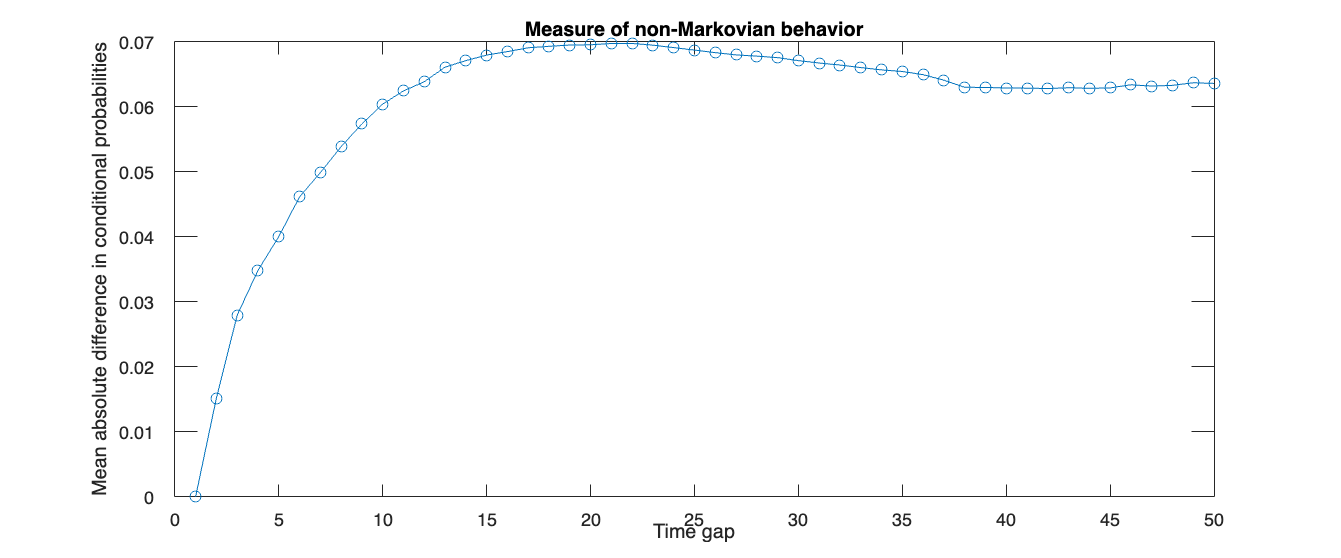

% Simulation parameters
total_time = 100;
N = 20; 
dt = 0.01;  
step_interval = 10;  % Visualize every 10th step

sigma = 1 + 3 * rand(N, 1);  % Particle diameters between 1-4
k_inter = 10; 
k_center = 1; 
mass = 0.5 + rand(N, 1);  % Particle masses between 0.5 and 1.5

% Initial conditions
x_0 = 10 * (rand(N, 3) - 0.5); 
v_0 = 2 * (rand(N, 3) - 0.5); 

[x, v, H] = Simulation(x_0, v_0, mass, sigma, k_inter, k_center, total_time, dt);

combined_visualization(x, v, H, sigma, mass, dt, step_interval);

q_vs_p_visualization(x, v, mass);

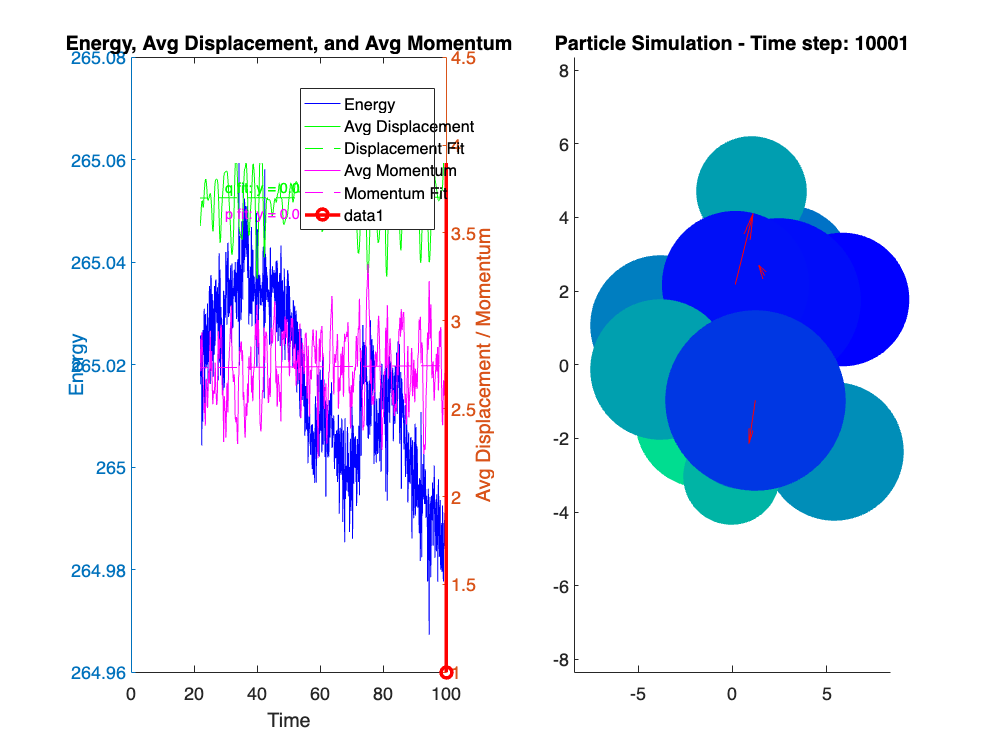

max_gap = 50;
markovian_scores = measure_markovian_property(H, max_gap);